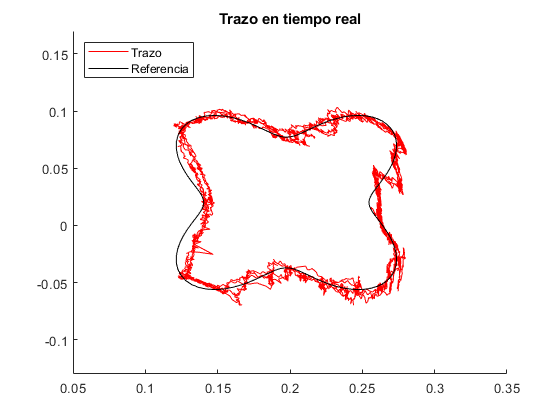

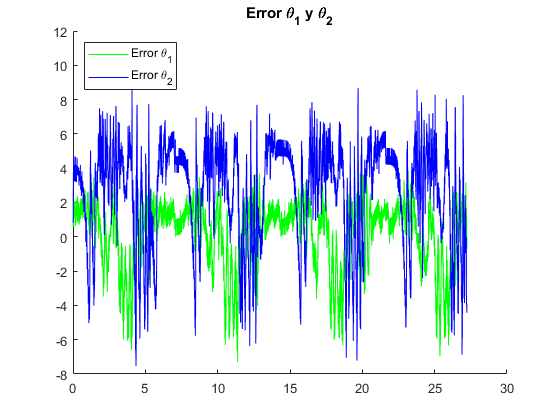

Error using split (line 83)
First argument must be text.

clearvars
clearAllMemoizedCaches
clear ;clc;close all;

figure; hAxes(1) = gca; fig(1) = gcf;title("Trazo en tiempo real");axis([0.05 0.35 -0.13 0.17]);legend("Location","northwest");
hAnimatedLine(1) = animatedline( hAxes(1),'Color','r','lineWidth',0.1,"DisplayName","Trazo");
hAnimatedLine(2) = animatedline( hAxes(1),'Color','k',"DisplayName","Referencia");
figure; hAxes(2) = gca;fig(2) = gcf;title("Error \theta_1 y \theta_2"); legend("Location","northwest");%ylim([-10 10]);
hAnimatedLine(3) = animatedline( hAxes(2),'Color','g','lineWidth',0.1,"DisplayName","Error \theta_1");
hAnimatedLine(4) = animatedline( hAxes(2),'Color','b','lineWidth',0.1,"DisplayName","Error \theta_2");


device = serialport("COM",115200);
configureTerminator(device,"CR");
pause(1);
T=input("Tiempo de ciclo\n");
writeline(device,"<"+string(T)+">");
pause(0.05)
E=input("Escala del trébol\n");
writeline(device,"<"+string(E)+">");
pause(0.05)
A=input("Ángulo de giro\n");
writeline(device,"<"+string(A)+">");
writeline(device,"<0>");


pause(10)
readline(device);
for i=1:(10/0.001)
    Linea=readline(device);
    vals(i,:)=str2double(split(Linea)');
    thetas(i,:)=fkine(vals(i,4),vals(i,8));
    thetasT(i,:)=fkine(vals(i,3),vals(i,7));
    if(thetas(i,2)>-0.1)
       addpoints(hAnimatedLine(1),thetas(i,1),thetas(i,2)); 
       addpoints(hAnimatedLine(2),thetasT(i,1),thetasT(i,2)); 
       addpoints(hAnimatedLine(3),(i*0.004),vals(i,5)); 
       addpoints(hAnimatedLine(4),(i*0.004),vals(i,9)); 
    end
    drawnow limitrate
end

clear device

function posX=SposX(E,theta_i)
    theta=linspace(0,2*pi,200);
    L=0.15;rel=0.5;dX=0.10;
    Tam=L/2;a=Tam*0.5/(tan((0.5+rel/2)*pi/2));b=Tam-a;
    posX=dX + (E.*L)./2 + E.*cos(theta).*(b + a.*cos(4.*theta + 4.*theta_i));
end

function posZ=SposZ(E,theta_i)
    theta=linspace(0,2*pi,200);
    L=0.15;rel=0.5;dZ=0.02;
    Tam=L/2;a=Tam*0.5/(tan((0.5+rel/2)*pi/2));b=Tam-a;
    posZ=dZ + E.*sin(theta).*(b + a.*cos(4.*theta + 4.*theta_i));
end



function DK=fkine(T1,T2)
    L1=0.18;
    L2=0.13;
    DK=zeros(length(T1),2);
    DK(:,1)=L1.*cosd(T1-90)+L2.*cosd(T1-90+T2);
    DK(:,2)=L1.*sind(T1-90)+L2.*sind(T1-90+T2);
end
